# DC motor speed control: PID

## Design Requirements

- Settling time less than 2 seconds

- Overshoot less than 5%

- Steady-state error less than 1%

## Design

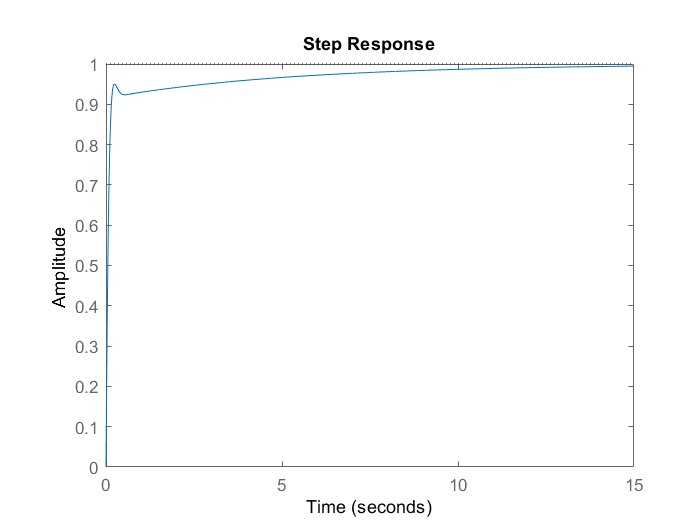

J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2);

kp = 100;
ki = 20;
kd = 6; % use kd to suppress overshoot
C = pid(kp, ki, kd);
sys_cl = feedback(C*P_motor, 1);
step(sys_cl)

In this case, the long tail on the step response graph is due to the fact that the integral gain is small and, therefore, it takes a long time for the** integral action to build up an**d eliminate the steady-state error. This process can be sped up by increasing the value 

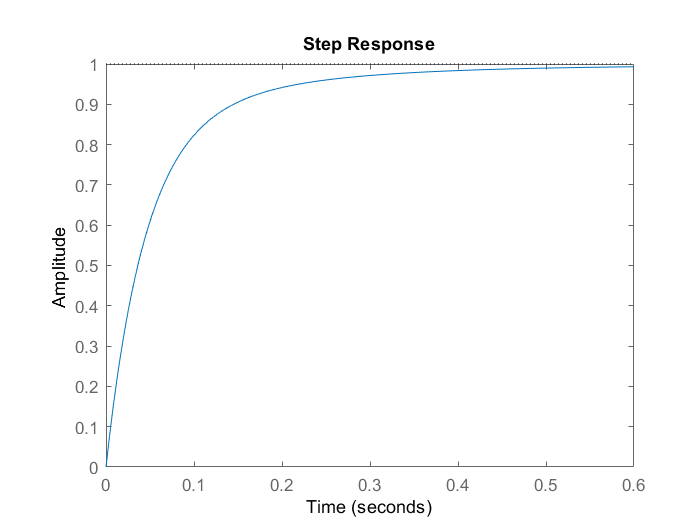

kp = 100;
ki = 150;
kd = 10;
C = pid(kp, ki, kd);
sys_cl = feedback(C*P_motor, 1);
step(sys_cl)